**LEP 5-5 : Effect of Pressure drop on Conversion**

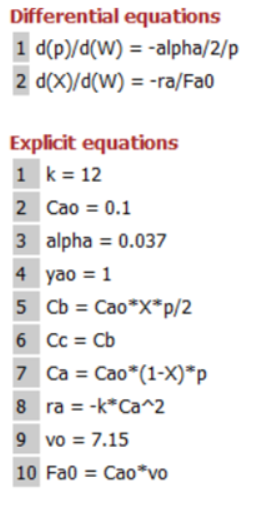

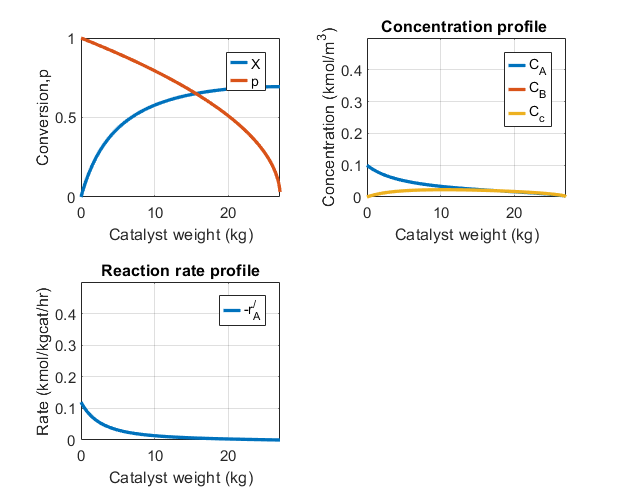

Vspan = [0 27];  
y0 = [0,1]; 
k = 12; 
Cao = 0.1;
vo=7.15;
alpha = 0.037;  
[v,y]=ode45(@(v,y)ODEfun(v,y,k,Cao,vo,alpha),Vspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,500,400])
nexttile
plot(v,y(:,1),v,y(:,2),'LineWidth',2)
xlabel('Catalyst weight (kg)')
ylabel('Conversion,p')
leg=legend('X','p');
leg.ItemTokenSize=[10,10];
axis([0 27 0 1])
grid on
z=size(y);
for i=1 : z(1,1)
    % Calculating the values of rate from its expression 
   Ca(i) = Cao*(1-y(i,1))*y(i,2);
   ra(i) = -k*Ca(i)^2; 
   Cb(i) = Cao*y(i,1)*y(i,2)/2;
   Cc(i) = Cb(i);
end
nexttile
plot(v,Ca(1:z(1,1)),v,Cb(1:z(1,1)),v,Cc(1:z(1,1)),'LineWidth',2)
xlabel('Catalyst weight (kg)')
ylabel('Concentration (kmol/m^3)')
leg=legend('C_A','C_B','C_c');
leg.ItemTokenSize=[10,10];
title('Concentration profile ')
grid on
axis([0 27 0 0.5])
nexttile
plot(v,-ra(1:z(1,1)),'LineWidth',2)
xlabel('Catalyst weight (kg)')
ylabel('Rate (kmol/kgcat/hr)')
leg=legend('-r_A^/');
leg.ItemTokenSize=[10,10];
title('Reaction rate profile')
grid on
axis([0 27 0 0.5])

function dYfuncvecdW = ODEfun(V,Yfuncvec,k,Cao,vo,alpha); 
X = Yfuncvec(1); 
p= Yfuncvec(2); 
% Explicit equations
Fa0 = Cao*vo;
Ca = Cao*(1-X)*p;
Cb = Cao*X*p/2;
Cc = Cb;
ra = -k*Ca^2; 
% Differential equations
dXdW = -ra/Fa0; 
dpdW = -alpha/2/p; 
dYfuncvecdW =[dXdW; dpdW]; 
end

